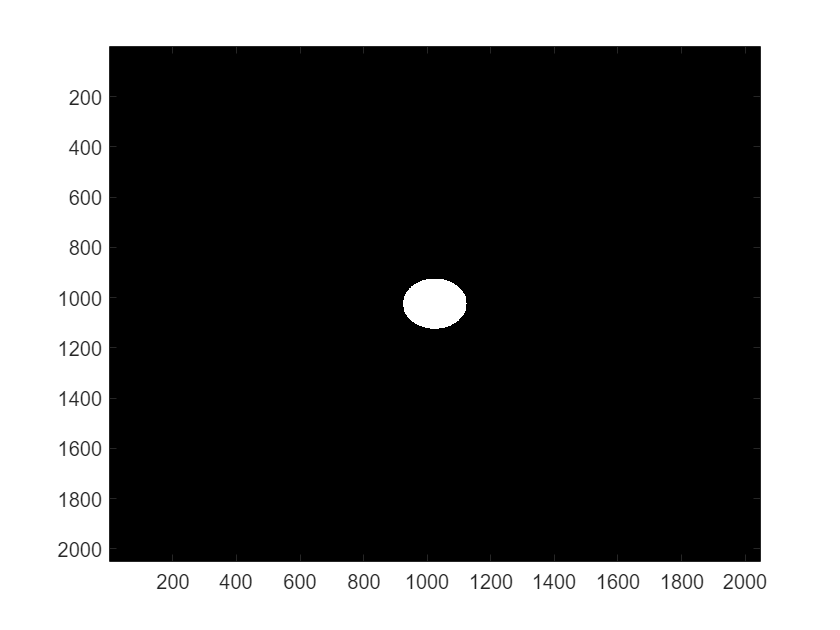

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 1;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
dx = 6.513*mm/(Nx*M); 
dy = dx;

% Longitud de Onda de iluminación
lambda = 650*nm;

% Apertura númerica
AN = 0.25;

%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;
 

%Leer imagenes 

tamanoImagen = 2048;

estrella = 'SiemensStar_2048_AD.png';
usaf = 'usaf.jpg';

nombre = usaf;

if strcmp(nombre,estrella) 
    tamanoImagen = 2048;
elseif strcmp(nombre,usaf)
    tamanoImagen = 780;
end 

% Imagen1 = imread(nombre);
% Imagen1 = imresize(im2gray(Imagen1), Nx/tamanoImagen);
% Imagen2 = imread(nombre);
% Imagen2 = imresize(im2gray(Imagen2), Nx/tamanoImagen);
% Imagen3 = imread(nombre);
% Imagen3 = imresize(im2gray(Imagen3), Nx/tamanoImagen);

Imagen1 = filtroCircular([Nx/2 Ny/2], 100, [Nx Ny]);
Imagen2 = filtroCuadrado([(Nx/2)-100 Ny/2], [100 100], [Nx Ny]);
Imagen3 = filtroCircular([(Nx/2)+100 Ny/2], 300, [Nx Ny]);

Imagen1 = im2gray(im2double(Imagen1));
%Imagen1 = ~Imagen1;
Imagen2 = im2gray(im2double(Imagen2));
%Imagen2 = ~Imagen2;
Imagen3 = im2gray(im2double(Imagen3));
%Imagen3 = ~Imagen3;


imagesc(Imagen1)
colormap("gray")

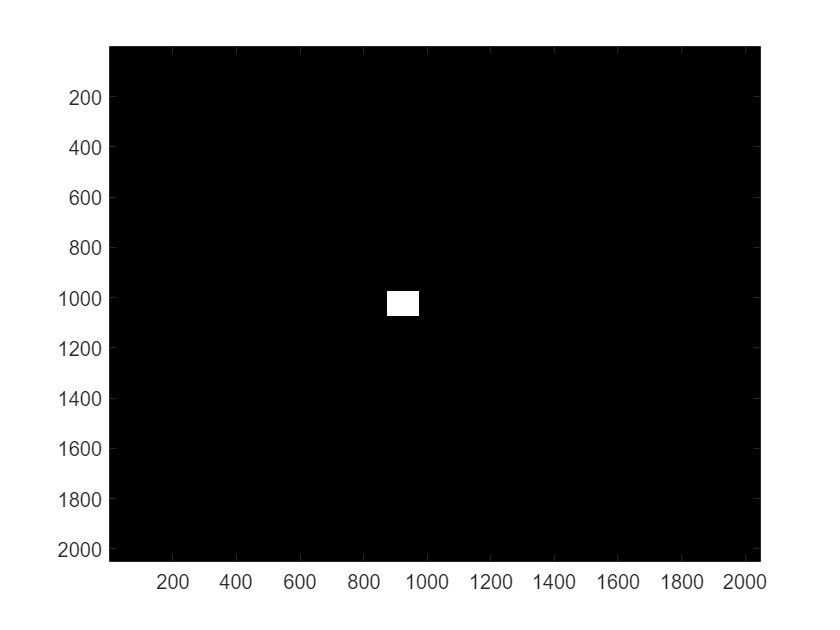

imagesc(Imagen2)
colormap("gray")

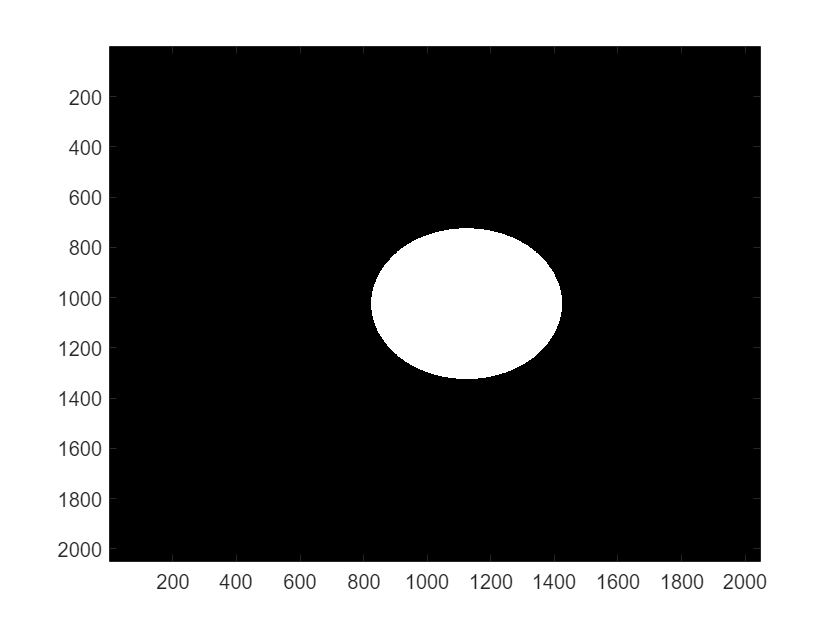

imagesc(Imagen3)
colormap("gray")


%Proceso para un microscopio de un foton. 

%Se usara un indicador para elegir el plano focal, si el
%que contiene a la imagen 1, 2 o 3. 

indicador = 1; 

% if indicador == 1
    %La imagen uno se encontrara en foco, por lo que no deberá hacerse
    %propagación inicial. 
    [salidafocal, observacion, pupila] = microscopio(Imagen1,M,f2,AN,Nx,Ny,dx,dy,lambda);

rpupila = 2505

    cadena = "primera imagen microscopio"

cadena = "primera imagen microscopio"

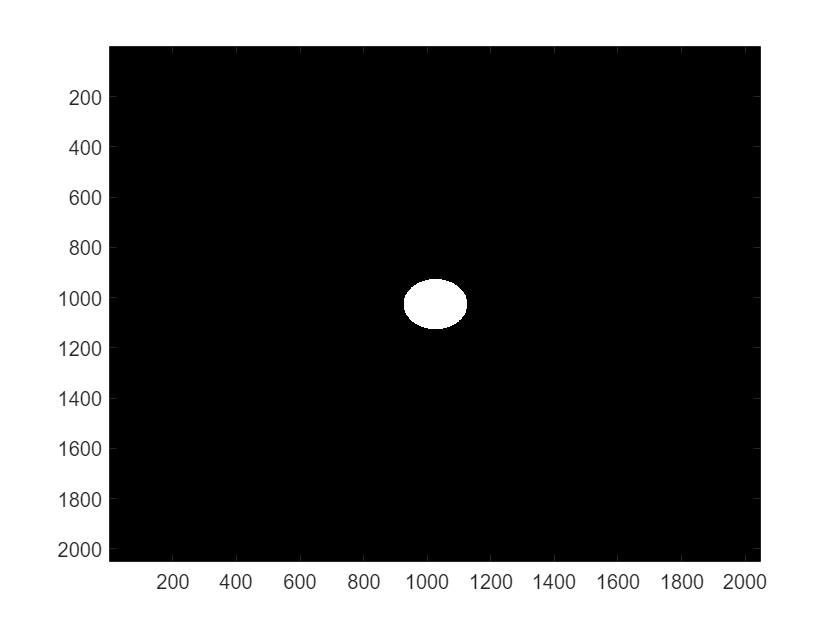

    salidafocalmod = (abs(salidafocal)).^2;
    imagesc(salidafocalmod)

    %La imagen dos se encontrara fuera de foco por 10 mm, por lo que
    %primero se debe propagar hasta el plano focal. En este caso usaremos
    %(Definir que propagación usar). 

    distIm2 = 1000*um;
    
    Imagen2Prop = espectroAngular(Imagen2, dx,dy,Nx,Ny,distIm2,lambda);
 
    %La imagen tres se encontrara fuera de foco por 20mm, por lo que primero
    %se debe propagar hasta el plano focal. 

    
    cadena1 = "figura2"

cadena1 = "figura2"

    Imagen2Propmod = (abs(Imagen2Prop)).^2;
    [salida2, observacion2, pupila2] = microscopio(Imagen2Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);

rpupila = 2505

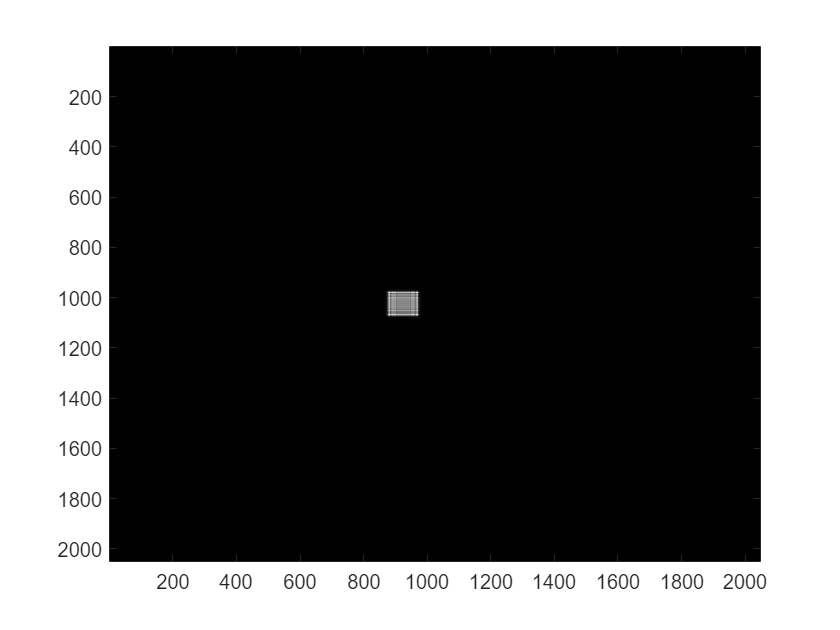

    salida2mod = (abs(salida2)).^2;
    imagesc(Imagen2Propmod)

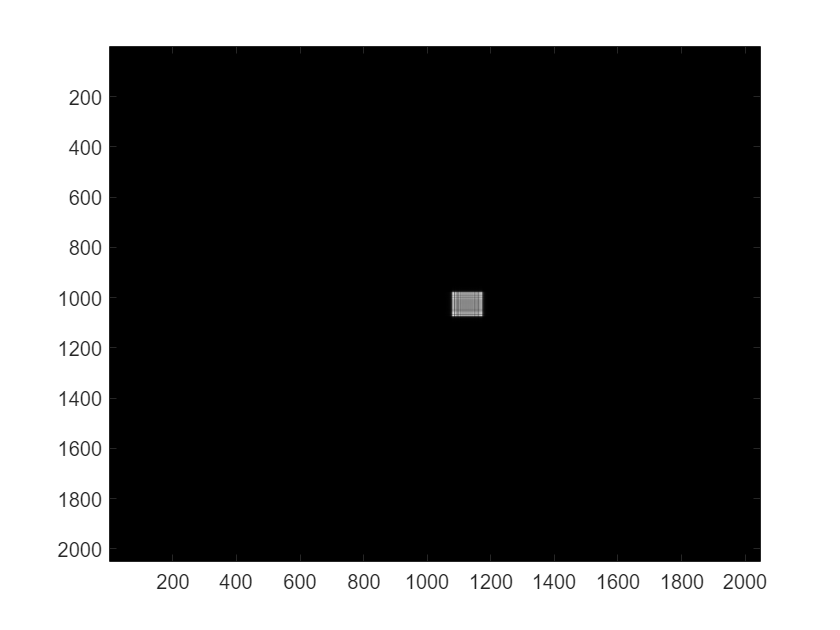

    imagesc(salida2mod)


    distIm3 = 2000*um;

    Imagen3Prop = espectroAngular(Imagen3, dx,dy,Nx,Ny,distIm3,lambda);
    
    
    cadena2 = "figura3"

cadena2 = "figura3"

    Imagen3Propmod = (abs(Imagen3Prop)).^2;
    [salida3, observacion3, pupila3] = microscopio(Imagen3Prop, M, f2, AN, Nx, Ny, dx, dy, lambda);

rpupila = 2505

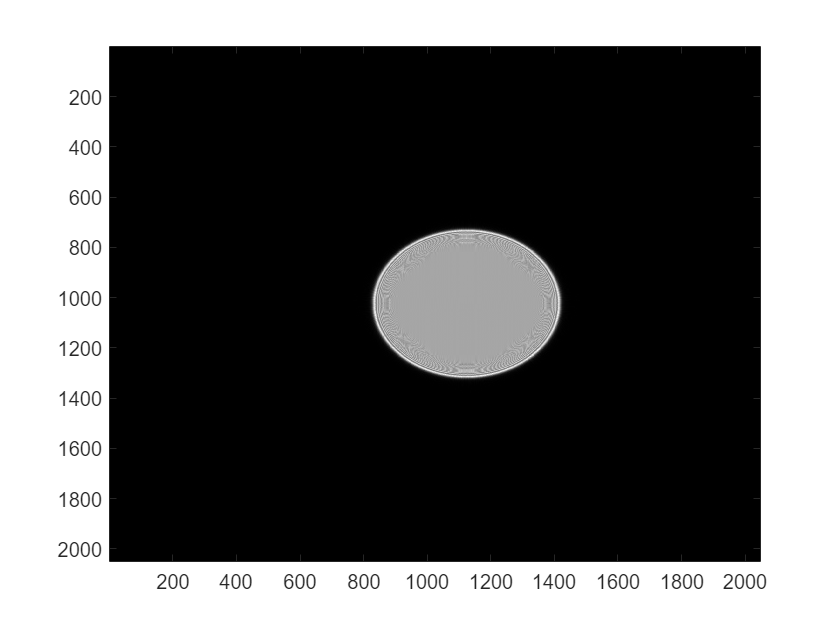

    salida3mod = (abs(salida3)).^2;
    imagesc(Imagen3Propmod)

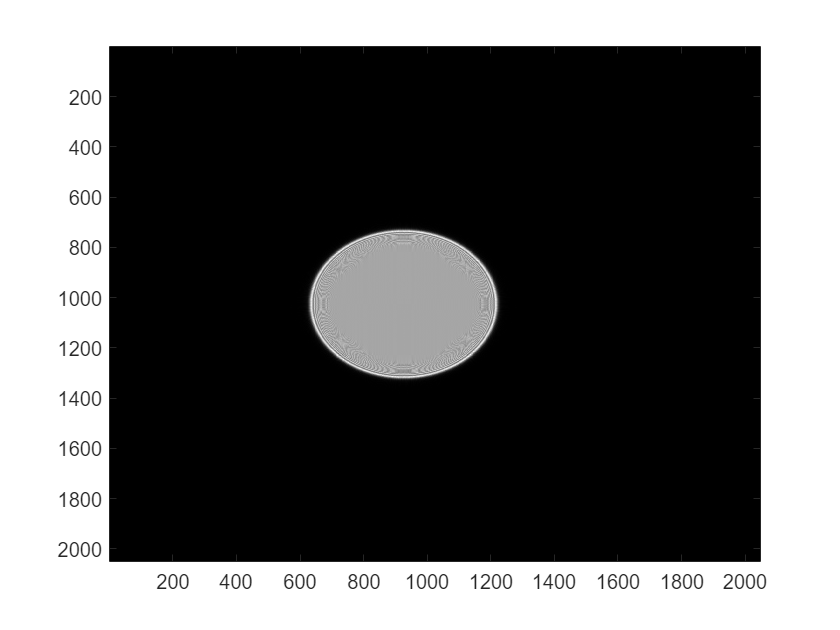

    imagesc(salida3mod)

    
    colormap("gray")

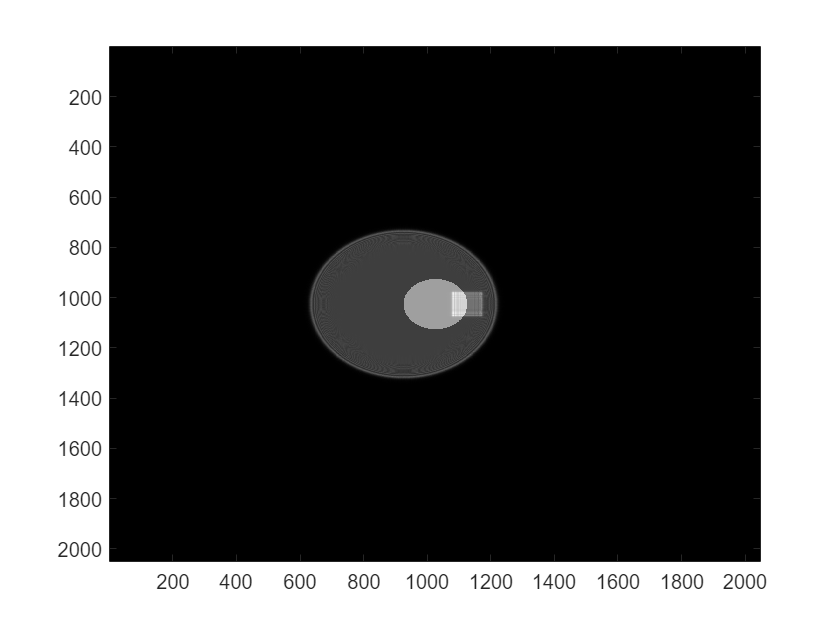

    
% elseif indicador == 2
%     [salidafocal, observacion, pupila] = microscopio(Imagen2,M,f2,AN,Nx,Ny,dx,dy,lambda)
% else
%     [salidafocal, observacion, pupila] = microscopio(Imagen3,M,f2,AN,Nx,Ny,dx,dy,lambda)
% end

%normalización

observacion = (observacion-min(observacion,[],"all"))./(max(observacion,[],"all")-min(observacion,[],"all"));

observacion2 = (observacion2-min(observacion2,[],"all"))./(max(observacion2,[],"all")-min(observacion2,[],"all"));

observacion3 = (observacion3-min(observacion3,[],"all"))./(max(observacion3,[],"all")-min(observacion3,[],"all"));

superposicionFinal = observacion+observacion2+observacion3;
superposicionFinalmod = ((abs(superposicionFinal)).^2);
imagesc(superposicionFinal)